# `Ex010 - ARPES Eb(kx) Data Processing at ADRESS`

This example shows how to perform common operations on ARPES data using the functions of the MATools and PESTools toolkit.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

close all; clear all;
pp          = plot_props();
path_data   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ARPEScape\ARPEScape-v8.0.0\PESTools_PCC\Examples\Example_Data\';
path_save   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ARPEScape\ARPEScape-v8.0.0\PESTools_PCC\Examples\Example_Data_Saved\';

# **ARPES Eb(kx) Data Processing**

help load_adress_data;

  dataStr = load_adress_data(FileName, PathName)
    This function loads in the HDF5 data files of ARPES data from 
    the ADRESS beamline at the SLS. The output is a MATLAB
    data-structure that yields all the data and information. This function 
    should be used to load in a single ADRESS data-file that is unprocessed
    or has been previously processed using PESTools. Last updated in
    October 2022, and includes electrostatic tilt extraction.
 
    REQ. FUNCTIONS:
    -   [data, axes, note]  = ReaderHDF5(fname);
 
    IN:
    -   FileName:           char of the input .h5 or .mat file-name.
    -   PathName:           char of the input .h5 or .mat directory path.
 
    OUT:
    dataStr - MATLAB data structure containing all fields below;
 	 .(FileName):       string of the current filename of the data file.
 	 .(H5file):         string of the raw .H5 filename of the data file.
 	 .(TimeStamp):      time-stamp of when the file was created.
 	 .(Type):         

**(A) Loading in the ARPES data files**

% Load in ARPES data
file_names      = {...
    '010_ARPES_HSCUT.h5',...
    };
arpes_dat = cell(1,length(file_names));
for i = 1:length(file_names); arpes_dat{i} = load_adress_data(file_names{i}, path_data); end

Loading ADRESS data...


for i = 1:length(arpes_dat); arpes_dat{i} = xcorr_scans(arpes_dat{i}); end

- Correlating scans
Scan = 2: Offset = 0.01728
Scan = 3: Offset = 0.01728
Scan = 4: Offset = 0.01728
Scan = 5: Offset = 0.02592
Scan = 6: Offset = 0.02592
Scan = 7: Offset = 0.02592
Scan = 8: Offset = 0.02592
Scan = 9: Offset = 0.02592
Scan = 10: Offset = 0.02592
Scan = 11: Offset = 0.03456
Scan = 12: Offset = 0.03456
Scan = 13: Offset = 0.03456
Scan = 14: Offset = 0.03456
Scan = 15: Offset = 0.03456


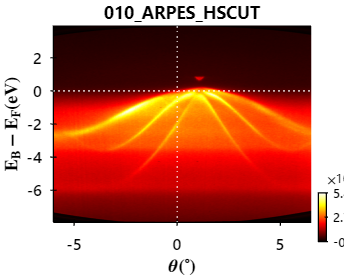

view_arpes_data(arpes_dat{1});

**(B) Loading in the Fermi-Edge reference files**

% Load in reference data
file_names_ref      = {...
    '010_ARPES_HSCUT_EF.h5',...
    };
arpes_ref = cell(1,length(file_names_ref));
for i = 1:length(file_names_ref); arpes_ref{i} = load_adress_data(file_names_ref{i}, path_data); end

Loading ADRESS data...


for i = 1:length(arpes_ref); arpes_ref{i} = xcorr_scans(arpes_ref{i}); end

- Correlating scans
Scan = 2: Offset = 0
Scan = 3: Offset = 0
Scan = 4: Offset = 0
Scan = 5: Offset = 0
Scan = 6: Offset = 0
Scan = 7: Offset = 0
Scan = 8: Offset = 0
Scan = 9: Offset = 0


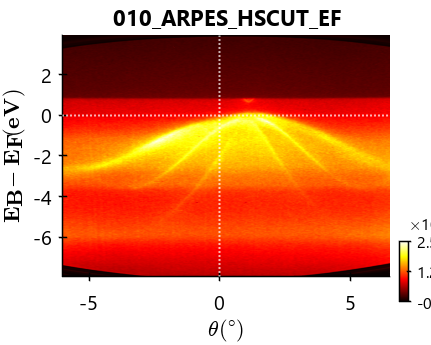

view_arpes_data(arpes_ref{1});

**(C) Binding energy alignment to the reference data**

help align_energy; close all;

  [dataStr, dataStr_ref] = align_energy(dataStr, align_args, dataStr_ref, plot_result)
    - #1 - FIRST STEP IN PROCESSING ARPES DATA
    This is a function that will align the 'dataStr' ARPES data-structure 
    to the Fermi-level, a peak, or reference VB or CB state. The energy
    alignment is done using various approaches that the user can select from,
    either using the 'dataStr' or a reference 'dataStr_ref' data file. 
        (1) 'align2ref'  : aligns to some peak or edge reference using MATools AlignEF() function.
        (2) 'fit2ef'    : fits directly to the FDD edge of a reference. 
        (3) 'fit2peak'  : fits directly to some peak feature.
        (4) 'gsv1s'     : global shift via one scan aligned to some peak / edge reference using MATools AlignEF() function.
 
    IN:
    -   dataStr:            data structure of the ARPES data.
    -   align_args:         {1×7} cell of {Type,Scans,eWin, dEWin, dESmooth, feat}.
                                Type: 

- EF alignment


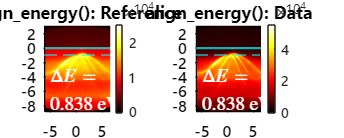

% - AUTOMATIC COARSE ALIGNMENT TO THE EDGE OF THE REFERENCE
% -- Coarse alignment of the energy
alignType   = "align2ref";
scan_indxs	= [];
eWin        = 0.80;
dEWin       = 1.50;
dESmooth    = [];
feat        = 'edge';
kWin        = 0.95;
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat, kWin};
for i = 1:length(arpes_dat)
    [arpes_dat{i}, arpes_ref{i}]  = align_energy(arpes_dat{i}, align_args, arpes_ref{i}, 1);
end

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


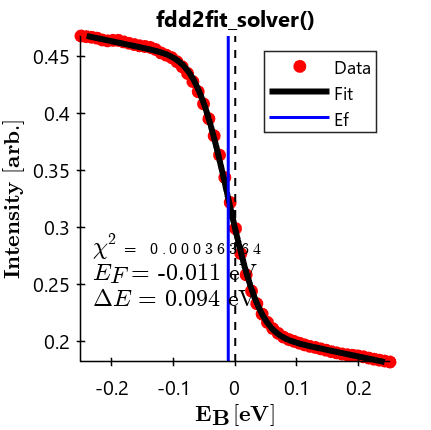

Ef = -0.0114

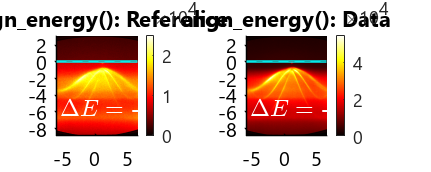

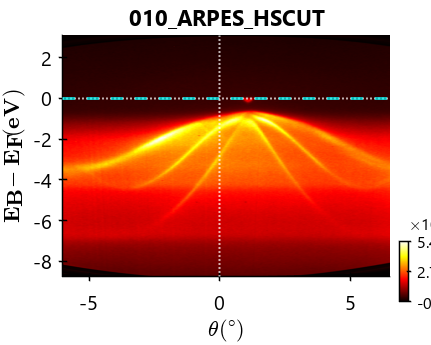

% - FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ef"; 
scan_indxs	= [];
eWin        = 0.00;
dEWin       = 0.25;
dESmooth    = [];
feat        = 'edge';
kWin        = 0.95;
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat, kWin};
for i = 1:length(arpes_dat)
    arpes_dat{i}  = align_energy(arpes_dat{i}, align_args, arpes_ref{i}, 1); 
    view_arpes_data(arpes_dat{i}); yline(0, 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 
end

**(D) Background subtraction and intensity normalisation**

help bgrd_subtr_data; close all;

  dataStr = bgrd_subtr_data(dataStr, bsub_args, plot_result)
    - #2 - SECOND STEP IN PROCESSING ARPES DATA
    This is a function that will background subtract / normalise the ARPES data using several
    different approaches over a given window.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
    -   DataC=SetContrast(Data,minFrac,maxFrac [,gamma]);
 
    IN:
    -   dataStr:        data structure of the ARPES data.
    -   bsub_args:      {1×5} cell of {bgrdType,bgrdWin,bgrdScale,bgrdSmooth,normType}.
                                bgrdType:       "AngleInt"
                                                "AngleInt-clip"
                                                "AngleInt-mean"
                                                "AngleInt-pctile"
                                                "AngleInt-mean-moving"
                                                "AngleInt-pctile-moving"
                               

- Angle integrating


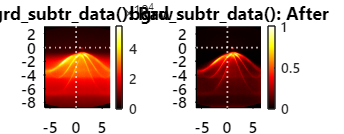

bgrdType    = "AngleInt-clip";
bgrdWin     = [];
bgrdScale   = 0.75;
bgrdSmooth  = 25;
normType    = "max-each";
bgrd_args   = {bgrdType, bgrdWin, bgrdScale, bgrdSmooth, normType}; 
for i = 1:length(arpes_dat)
    arpes_dat{i} = bgrd_subtr_data(arpes_dat{i}, bgrd_args, 1); 
end

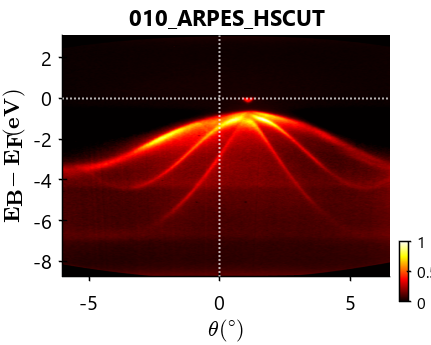

view_arpes_data(arpes_dat{1});

**(E) Wave-vector conversions**

help convert_to_k; close all; 

  dataStr = convert_to_k(dataStr, kconv_args, plot_result)
    - #3 - THIRD STEP IN PROCESSING ARPES DATA
    This is a function that will convert the angles thtA into kx and the
    scan parameters into either ky (for tltM) or kz (for hv).  Last updated in
    October 2022, and includes input for new X-ray incidence angle.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
    -   surfNormX = SurfNormX(hv, eB_ref, kx_ref, thtM, thtA_ref) calculates the surface normal angle in the MP.
    -   Kxx = Kxx(HV, Eb, thtM, ThtA, surfNormX) calculates k// in the MP.
    -   Kyy = Kyy(HV, Eb, thtM, TltM, surfNormX) calculates k// in the MP.
    -   Kzz = Kzz(HV, Eb, thtM, ThtA, TltM, v000, surfNormX) calculates kz along the surface normal.
 
    IN:
    -   dataStr:        data structure of the ARPES data.
    -   kconv_args:     {1×5} cell of {eB_ref, kx_ref, thtA_ref, v000, incAlpha}.
                                eB_ref:    	single,

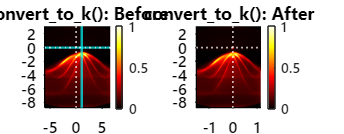

eB_ref      = 0;
kx_ref      = 0;
thtA_ref    = 1.067;
v000        = 12.57;
inc_alpha   = 9;
kconv_args  = {eB_ref, kx_ref, thtA_ref, v000, inc_alpha}; 
for i = 1:length(arpes_dat)
    arpes_dat{i} = convert_to_k(arpes_dat{i}, kconv_args, 1);
    % -- custom shift to centralise kx
    arpes_dat{i}.kx = arpes_dat{i}.kx - 0.0;
end

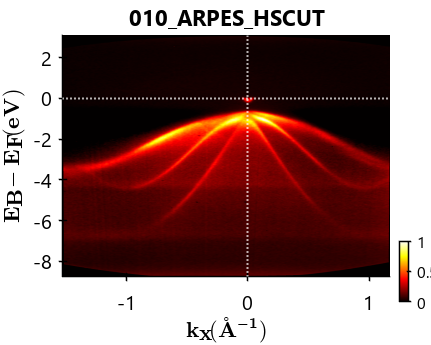

view_arpes_data(arpes_dat{1});

**(F) Cropping the ARPES data**

help data_crop3D; close all; 

  dataStr = crop_data(dataStr, xField_lims, yField_lims, zField_lims)
    This function crops the ARPES x-, y- and z-independent variables over
    a given range. The function crops the most recently processed data and
    ensures consistency across both the independent variables and data
    matrix.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
 
    IN:
    -   dataStr:        loaded MATLAB data structure.
  	-   xField_lims:    [1 x 2] row vector of xField ('raw_tht', 'tht', 'kx') crop limits.
  	-   yField_lims:    [1 x 2] row vector of yField ('raw_eb', 'eb') crop limits.
 	-   zField_lims:    [1 x 2] row vector of zField ('hv / tltM', 'kz / ky') crop limits.
 
    OUT:
    -   dataStr:        modified and cropped ARPES data structure.



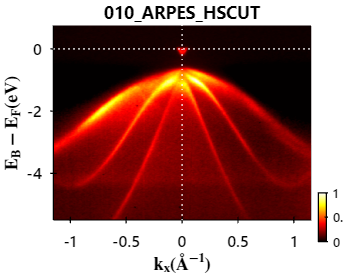

ans = struct with fields:
       FileName: '010_ARPES_HSCUT'
         H5file: '010_ARPES_HSCUT.h5'
      TimeStamp: "05-Oct-2021 16:58:40"
           Type: "Eb(k)"
          index: 1
           meta: [1×1 struct]
             hv: 586
           tltM: 2.8006
           tltE: 0
           thtM: 0
           Temp: 81.9000
       raw_data: [1376×391 double]
        raw_tht: [-6 -5.9679 -5.9359 -5.9038 -5.8718 -5.8397 -5.8077 -5.7756 -5.7436 -5.7115 -5.6795 -5.6474 -5.6154 -5.5833 -5.5513 -5.5192 -5.4872 -5.4551 -5.4231 -5.3910 -5.3590 -5.3269 -5.2949 -5.2628 -5.2308 -5.1987 -5.1667 -5.1346 -5.1026 … ]
         raw_eb: [1376×1 double]
      eb_shifts: {[1 0.8378]  [1 -0.0114]}
    eb_ref_file: {'010_ARPES_HSCUT_EF'  '010_ARPES_HSCUT_EF'}
             eb: [724×335 double]
            tht: [724×335 double]
           data: [724×335 double]
      surfNormX: 0.2919
             kx: [724×335 double]
             ky: 0.6034
             kz: 12.5153


xLims       = [-1.15, 1.15];    % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-5.5, 0.75];     % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
for i = 1:length(arpes_dat) 
    arpes_dat{i} = data_crop3D(arpes_dat{i}, xLims, yLims, zLims);
end
view_arpes_data(arpes_dat{1}); arpes_dat{1}

# **APPENDIX : A LIST OF USEFUL FUNCTIONS**

## Appendix I - Extracting *iso-cut* profiles

- Data cut formation


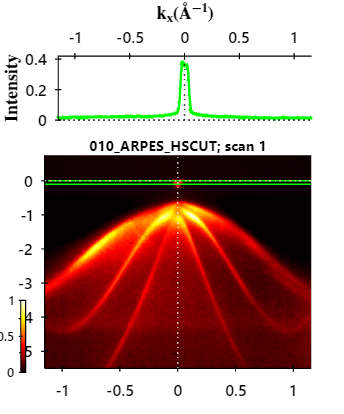

cutStr_01 = struct with fields:
    isocut_args: {[1]  ["MDC"]  [-0.1000 0]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "MDC"
         IsoVal: -0.0500
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [-1.1500 -1.1431 -1.1362 -1.1294 -1.1225 -1.1156 -1.1087 -1.1018 -1.0949 -1.0880 -1.0811 -1.0742 -1.0673 -1.0604 -1.0535 -1.0466 -1.0397 -1.0328 -1.0259 -1.0190 -1.0121 -1.0052 -0.9983 -0.9914 -0.9845 -0.9776 -0.9707 -0.9638 -0.9569 … ]
           DCut: [0.0205 0.0173 0.0167 0.0167 0.0170 0.0180 0.0201 0.0219 0.0190 0.0184 0.0189 0.0193 0.0190 0.0182 0.0194 0.0212 0.0217 0.0205 0.0192 0.0206 0.0213 0.0214 0.0222 0.0229 0.0220 0.0200 0.0207 0.0204 0.0194 0.0191 0.0203 0.0210 0.0215 … ]


nFrame          = 1;                    % Scan number to be cut
% -- EXTRACT MDC CUT
cutType         = "MDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.1, 0.0];          % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[cutStr_01, ~]  = extract_isoCut(arpes_dat{1}, isocut_args); cutStr_01

- Data cut formation


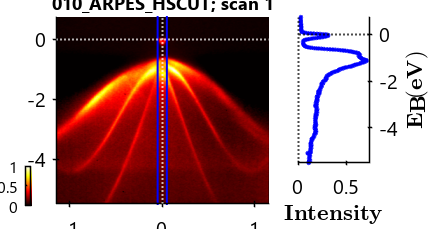

cutStr_02 = struct with fields:
    isocut_args: {[1]  ["EDC"]  [-0.0500 0.0500]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "EDC"
         IsoVal: 0
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [724×1 double]
           DCut: [724×1 double]


% -- EXTRACT EDC CUT
cutType         = "EDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.05, 0.05];        % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[cutStr_02, ~]   = extract_isoCut(arpes_dat{1}, isocut_args); cutStr_02

- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation


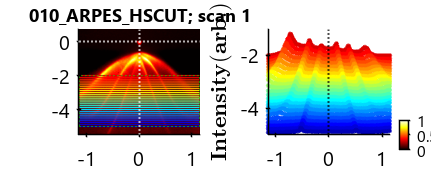

cutStr_03 = struct with fields:
    isocut_args: {[1]  ["MDC"]  [0.0500]  [-1.7500 1.7500]  [-5 -2]  [25]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "MDC"
         IsoVal: [-5 -4.8750 -4.7500 -4.6250 -4.5000 -4.3750 -4.2500 -4.1250 -4 -3.8750 -3.7500 -3.6250 -3.5000 -3.3750 -3.2500 -3.1250 -3 -2.8750 -2.7500 -2.6250 -2.5000 -2.3750 -2.2500 -2.1250 -2]
         IsoWin: [-0.0500 0.0500]
         IsoNum: 25
           XCut: {1×25 cell}
           DCut: {1×25 cell}


% -- EXTRACT SERIES OF MDC CUTS
isocutType          = "MDC";            % Type of line profile to extract. "EDC" (vertical) or "MDC" (horizontal)
isocutWin           = 0.05;             % single, constant valueof the integration window.
isocutXLims         = [-1.75, 1.75];    % 1x2 vector which gives the x-axis limits of the train [minX, maxX]
isocutYLims         = [-5, -2];         % 1x2 vector which gives the y-axis limits of the train [minY, maxY]
isocutN             = 25;               % single, constant value that determines the total number of line profiles to extract
isocut_args         = {nFrame, isocutType, isocutWin, isocutXLims, isocutYLims, isocutN};
plot_result         = 1;                % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[cutStr_03, ~]      = extract_isoCut_series(arpes_dat{1}, isocut_args, plot_result); cutStr_03

## Appendix II - Extracting kF using the gradient method

**(A) Crop the ARPES data around the CB**

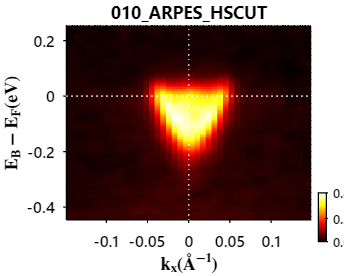

ans = struct with fields:
       FileName: '010_ARPES_HSCUT'
         H5file: '010_ARPES_HSCUT.h5'
      TimeStamp: "05-Oct-2021 16:58:40"
           Type: "Eb(k)"
          index: 1
           meta: [1×1 struct]
             hv: 586
           tltM: 2.8006
           tltE: 0
           thtM: 0
           Temp: 81.9000
       raw_data: [1376×391 double]
        raw_tht: [-6 -5.9679 -5.9359 -5.9038 -5.8718 -5.8397 -5.8077 -5.7756 -5.7436 -5.7115 -5.6795 -5.6474 -5.6154 -5.5833 -5.5513 -5.5192 -5.4872 -5.4551 -5.4231 -5.3910 -5.3590 -5.3269 -5.2949 -5.2628 -5.2308 -5.1987 -5.1667 -5.1346 -5.1026 … ]
         raw_eb: [1376×1 double]
      eb_shifts: {[1 0.8378]  [1 -0.0114]}
    eb_ref_file: {'010_ARPES_HSCUT_EF'  '010_ARPES_HSCUT_EF'}
             eb: [82×44 double]
            tht: [82×44 double]
           data: [82×44 double]
      surfNormX: 0.2919
             kx: [82×44 double]
             ky: 0.6034
             kz: 12.5153


xLims       = [-0.15, 0.15];    % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-0.45, 0.25];     % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
for i = 1:length(arpes_dat)
    arpes_dat{i} = data_crop3D(arpes_dat{i}, xLims, yLims, zLims);
    view_arpes_data(arpes_dat{i}); arpes_dat{i}
end

**(B) Binding energy re-alignment to make sure EF is correct**

- Angle integrating

Local minimum possible.
lsqcurvefit stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


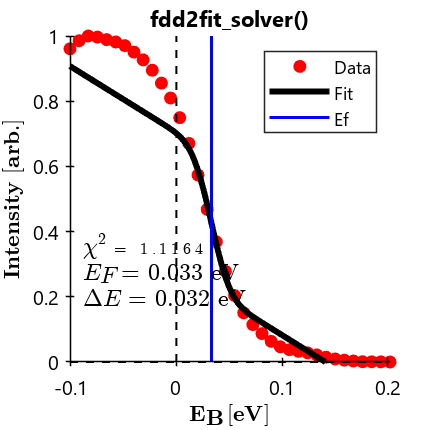

Ef = 0.0333

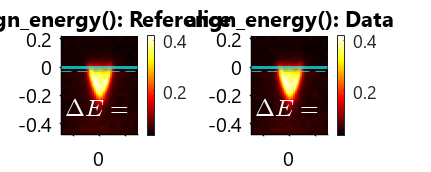

alignType   = "fit2ef";         % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];                   % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.05;                 % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.15;                 % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];                   % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';               % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
kWin        = 0.10;
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat, kWin};
for i = 1:length(arpes_dat)
    arpes_dat{i}  = align_energy(arpes_dat{i}, align_args, [], 1); 
end

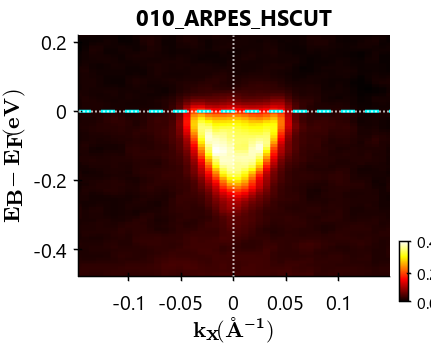

view_arpes_data(arpes_dat{1}); 
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(C) Extracting an MDC cut through the Fermi-edge**

- Data cut formation


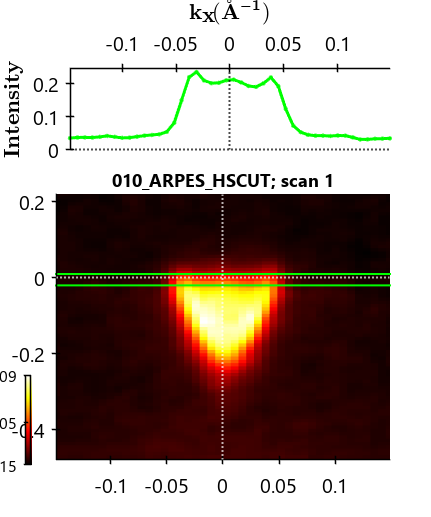

cutStr_01 = struct with fields:
    isocut_args: {[1]  ["MDC"]  [-0.1000 0]}
         xField: "kx"
       FileName: '010_ARPES_HSCUT'
           Type: "Eb(k)"
        IsoType: "MDC"
         IsoVal: -0.0500
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [-1.1500 -1.1431 -1.1362 -1.1294 -1.1225 -1.1156 -1.1087 -1.1018 -1.0949 -1.0880 -1.0811 -1.0742 -1.0673 -1.0604 -1.0535 -1.0466 -1.0397 -1.0328 -1.0259 -1.0190 -1.0121 -1.0052 -0.9983 -0.9914 -0.9845 -0.9776 -0.9707 -0.9638 -0.9569 … ]
           DCut: [0.0205 0.0173 0.0167 0.0167 0.0170 0.0180 0.0201 0.0219 0.0190 0.0184 0.0189 0.0193 0.0190 0.0182 0.0194 0.0212 0.0217 0.0205 0.0192 0.0206 0.0213 0.0214 0.0222 0.0229 0.0220 0.0200 0.0207 0.0204 0.0194 0.0191 0.0203 0.0210 0.0215 … ]


nFrame          = 1;                    % Scan number to be cut
cutType         = "MDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.02, 0.01];          % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[mdcStr, ~]     = extract_isoCut(arpes_dat{1}, isocut_args); cutStr_01

**(D) Extracting kF based on gradient method**

1) x = -0.05, y = 6.95 


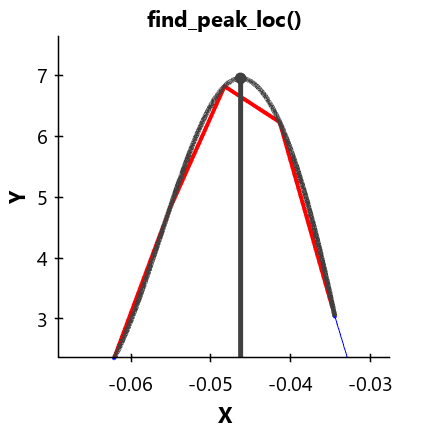

1) x = 0.05, y = 6.21 


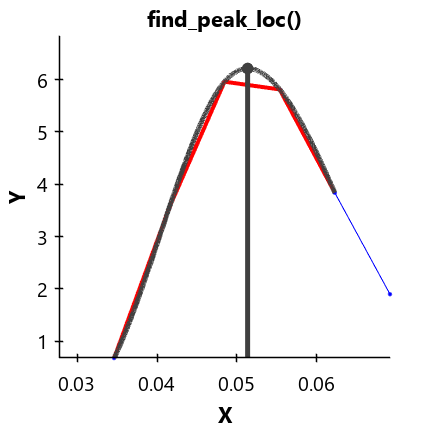

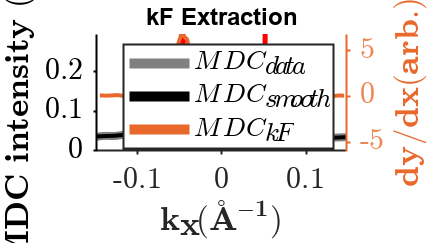

kfType          = "spline";
dkSmoothType    = "Gaco2";
dkSmoothVal     = 1.0;
kF_args         = {kfType, dkSmoothType, dkSmoothVal};
kfStr           = extract_kf(mdcStr.XCut, mdcStr.DCut, kF_args); 

kfStr

kfStr = struct with fields:
    kF_args: {["spline"]  ["Gaco2"]  [1]}
      XCut0: [-0.1485 -0.1416 -0.1347 -0.1278 -0.1209 -0.1140 -0.1070 -0.1001 -0.0932 -0.0863 -0.0794 -0.0725 -0.0656 -0.0587 -0.0518 -0.0448 -0.0379 -0.0310 -0.0241 -0.0172 -0.0103 -0.0034 0.0035 0.0104 0.0173 0.0243 0.0312 0.0381 0.0450 0.0519 … ]
      DCut0: [0.0362 0.0380 0.0381 0.0378 0.0398 0.0426 0.0397 0.0367 0.0375 0.0405 0.0436 0.0456 0.0477 0.0550 0.0823 0.1513 0.2202 0.2365 0.2108 0.2026 0.2034 0.2112 0.2131 0.2048 0.1938 0.1912 0.2020 0.2198 0.1932 0.1237 0.0738 0.0541 0.0459 … ]
      XCut1: [-0.1485 -0.1416 -0.1347 -0.1278 -0.1209 -0.1140 -0.1070 -0.1001 -0.0932 -0.0863 -0.0794 -0.0725 -0.0656 -0.0587 -0.0518 -0.0448 -0.0379 -0.0310 -0.0241 -0.0172 -0.0103 -0.0034 0.0035 0.0104 0.0173 0.0243 0.0312 0.0381 0.0450 0.0519 … ]
      DCut1: [0.0367 0.0376 0.0380 0.0385 0.0399 0.0410 0.0396 0.0379 0.0383 0.0405 0.0433 0.0458 0.0499 0.0624 0.0952 0.1509 0.2034 0.2230 0.2149 0.2060 0.2055 0.2093 0.2098 0.2039